P1. Implementati functii ce genereaza formule de cuadratura gaussiene pentru ponderile clasice date in tabela 1.

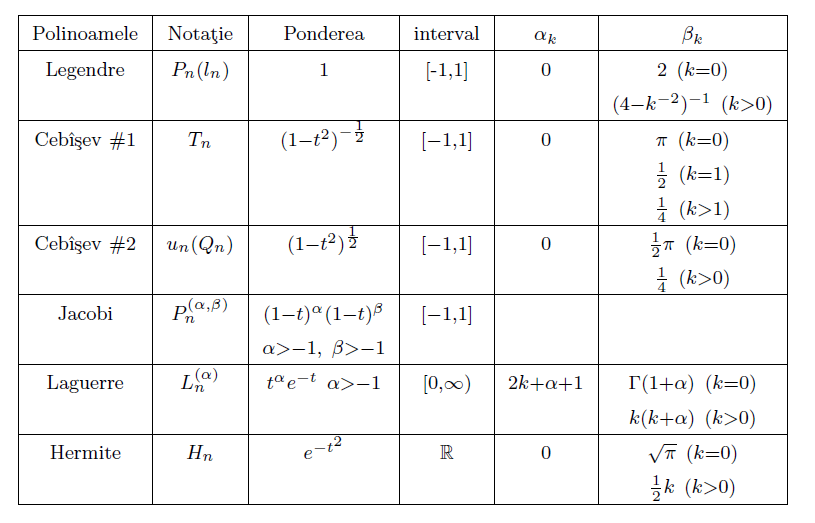

Legendre $\int_{-1}^1 \sin \left(x^2 \right)\textrm{dx}$

clear
syms x
f=@(x) sin(x .^ 2);
a = -1; b = 1; n = 5;

[g_nodes, g_coeff] = Legendre(n);
legendre_value = vquad(g_nodes, g_coeff, f);
real_value = quad(f, -1, 1);

fprintf("Aproximarea integralei prin Legendre: %f", legendre_value);

Aproximarea integralei prin Legendre: 0.620515

fprintf("Valoare reala: %f", real_value);

Valoare reala: 0.620537

Cebîșev #1 $\int_{-1}^1 \frac{\cos \left(x\right)}{\sqrt{1-x^2 }}\textrm{dx}$

clear
syms x
f=@(x) cos(x) / sqrt(1 - x .^ 2);
a = -1; b = 1; n = 10;

[g_nodes, g_coeff] = Cebisev1(n);
cebisev1_value = vquad(g_nodes, g_coeff, @cos);
real_value = double(int(f(x), x, a, b));

fprintf("Aproximarea integralei prin Cebîșev #1: %f", cebisev1_value);

Aproximarea integralei prin Cebîșev #1: 2.403939

fprintf("Valoare reala: %f", real_value);

Valoare reala: 2.403939

Cebîșev #2 $\int_{-1}^1 \sqrt{1-x^2 }\cos \left(x\right)\textrm{dx}$

clear
syms x
f=@(x) sqrt(1 - x .^ 2) / cos(x);
a = -1; b = 1; n = 10;

[g_nodes, g_coeff] = Cebisev2(n);
cebisev2_value = vquad(g_nodes, g_coeff, @cos);
real_value = double(int(f(x), x, a, b));

fprintf("Aproximarea integralei prin Cebîșev #2: %f", cebisev2_value);

Aproximarea integralei prin Cebîșev #2: 1.382460

fprintf("Valoare reala: %f", real_value);

Valoare reala: 1.822725

Jacobi $\int_{-1}^1 \sqrt{\frac{1-x}{1+x}}\frac{x^2 }{1+x^2 }\textrm{dx}$

clear
syms x
g = @(x) x .^ 2 ./ (1 + x .^ 2)

g = function_handle with value:
    @(x)x.^2./(1+x.^2)


f = @(x) sqrt((1 - x) / (1 + x)) * g(x)

f = function_handle with value:
    @(x)sqrt((1-x)/(1+x))*g(x)


a = -1/2; b = 1/2; n = 8;

[g_nodes, g_coeff] = Jacobi(n, a, b);
jacobi_value = vquad(g_nodes, g_coeff, g);
real_value = double(int(f, x, -1, 1));

fprintf("Aproximarea integralei prin Jacobi: %f", jacobi_value);

Aproximarea integralei prin Jacobi: 0.920153

fprintf("Valoare reala: %f", real_value);

Valoare reala: 0.920151

Laguerre $\int_0^{\infty } e^{-x} \;\sin \left(x\right)\textrm{dx}$

clear
syms x
f=@(x) exp(-x) * sin(x);
a = 0; b = Inf; n = 6;

[g_nodes, g_coeff] = Laguerre(n, a);
laguerre_value = vquad(g_nodes, g_coeff, @sin);
real_value = double(int(f(x), x, a, b));

fprintf("Aproximarea integralei prin Laguerre: %f", laguerre_value);

Aproximarea integralei prin Laguerre: 0.500049

fprintf("Valoare reala: %f", real_value);

Valoare reala: 0.500000

Hermite $\int_{-\infty }^{\infty } e^{{-x}^2 } \;\left(\cos \left(x\right)+\sin \left(x\right)\right)\textrm{dx}$

clear
syms x
f=@(x) cos(x) + sin(x);
a = -Inf; b = Inf; n = 10;

[g_nodes, g_coeff] = Hermite(n);
hermite_value = vquad(g_nodes, g_coeff, f);
real_value = double(int(exp(- x .^ 2) * f(x), x, a, b));

fprintf("Aproximarea integralei prin Hermite: %f", hermite_value);

Aproximarea integralei prin Hermite: 1.380388

fprintf("Valoare reala: %f", real_value);

Valoare reala: 1.380388